**Generate theory**

This is needed in order to compare experiments with ground truth. 

% First generate theory:
% w = 300;% minimum overlap length
% sF = 0.9:0.025:1.1;
timestamp = datestr(clock(), 'yyyy-mm-dd_HH_MM_SS');

fastas = {'018_final_polish.fasta','DA32087.fasta','DA68335.fasta'};
theoryIdxs = {1, 3, 2, nan, 2 , 2, 3}; % known theory indexes
dataSetIdx = 3; % 5,... test datasets (part of the data)

nmPerPx = 110;
nmbp = 0.25; % ? 
alphaNu1 = 0.085; % 0.08 default for the paper


% quickly calculate theory for given single fasta file
[theoryStructRev,theoryStruct,bT] = prep_thry_for_local_comp(fastas(theoryIdxs{dataSetIdx}), nmbp, nmPerPx, 1);

Computing free concentrations
Elapsed time is 0.856894 seconds.
Finished computing free concentrations
loaded theory sequence DA32087.fasta
Nm/bp ratio not converted. At least one barcode has nmbp lower than user-input


## **Motivation**

Mean and standard deviation along the theory is not constant. Therefore one has to write an algorithm that takes this into account

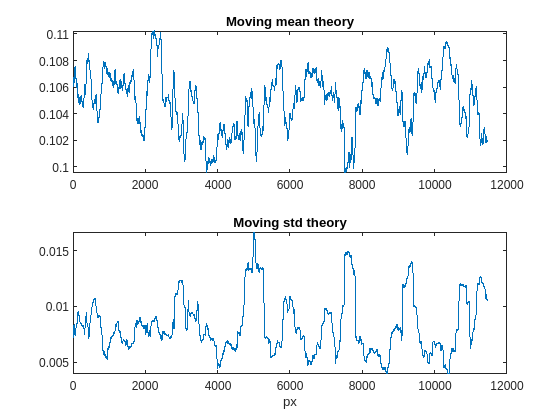

w = 300;

thrMean = arrayfun(@(x) mean(theoryStruct.rawBarcode(x:x+w-1)),1:length(theoryStruct.rawBarcode)-w+1);
thrStd = arrayfun(@(x) std(theoryStruct.rawBarcode(x:x+w-1)),1:length(theoryStruct.rawBarcode)-w+1);

figure;tiledlayout(2,1);
nexttile
plot(thrMean)
title('Moving mean theory')
nexttile
plot(thrStd)
title('Moving std theory')
xlabel('px')

## **Data**

We use some experimental dataset (for synthetic check other mlx)

[oS,barcodeGen, barsetGen, outConsensus, coverage, consensus, islandElts, islandPx,cGenAll,barcodeIslandsData, barStruct,barIslands,sortedVals, sortedIds] = Core.prep_data('dEC');
% [oS,barcodeGen, barsetGen, outConsensus, coverage, consensus, islandElts, islandPx,cGenAll,barcodeIslandsData, barStruct,barIslands,sortedVals, sortedIds] = ...
%     Core.prep_data('dECind',7);

% otherwise take data from final_figure_6


## **Visualization**

If one wants to show one of the pairs

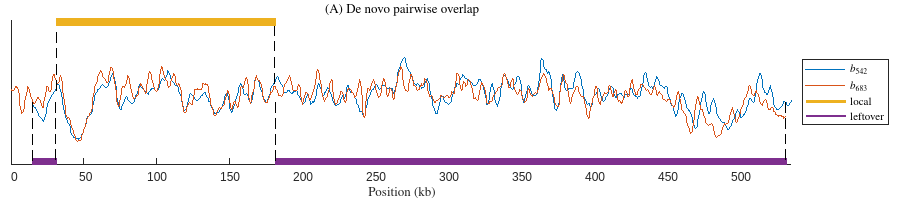

idxPair = 42;
f=figure('Position', [10 10 900 200]); g=tiledlayout(1,2,'TileSpacing','tight','Padding','none');
[curSink,curSource] = ind2sub(size(oS),sortedIds(idxPair));
% curSink = 151;
% curSource = 312;
import Plot.pair_evaluation_with_ground_truth_simple_plot; % todo: convert comparisonStructC to overlap for this plot (using something like synth_to_struct)
pair_evaluation_with_ground_truth_simple_plot(barcodeGen, oS,curSink,curSource,[],[],g);

Scale original barcodes from table representation to block representation. blockRep-cGen - simple conversion

wminC = 300;

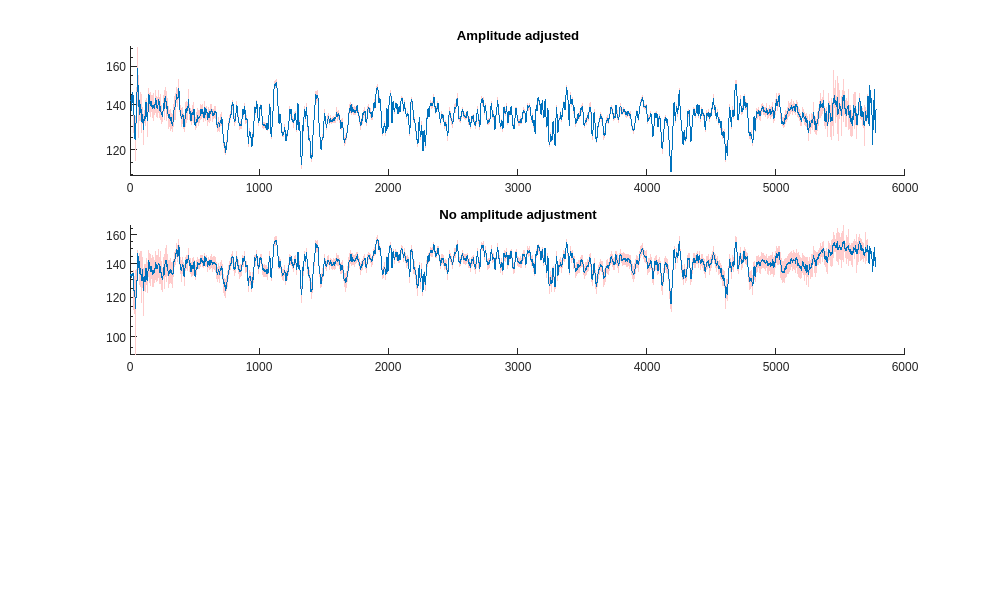

ans =   Figure (24) with properties:

      Number: 24
        Name: ''
       Color: [1 1 1]
    Position: [1 1 1000 600]
       Units: 'pixels'

  Show all properties


ix = 1;
import Core.barcode_island_consensus;
    [aaBarcodeIslandBlockRepV, ~,~,clusterBarcodesV,rawBarcodeIslandBlockRep] = barcode_island_consensus(barcodeGen,cGenAll, ix, wminC);

[aaBarcodeIslandBlockRepV, Z , allscores,clusterBarcodesV,rawBarcodeIslandBlockRep] = barcode_island_consensus(barcodeGen,cGenAll, ix, wminC,alphaNu1);


consensus_ci(aaBarcodeIslandBlockRepV,rawBarcodeIslandBlockRep);

**Temporary consensus using nanmean**

con1 = mean(aaBarcodeIslandBlockRepV,'omitnan');
conz = mean(outConsensus{ix},'omitnan');
% figure,plot((con1-nanmean(con1))/nanstd(con1,1))
% hold on,plot((conz-nanmean(conz))/nanstd(conz,1))
% legend({'New scaling','Z-score'}) 

Compare the consensus barcode against theory using matrix profile (MP) 

wmin = 200;
numWorkers = 30;
sets.comparisonMethod = 'mpnan';
sets.nuF = 0.08;
sets.w = 300;

sF = 0.85:0.01:1.15;
bar =[];
bar{1}.rawBarcode = con1;
bar{1}.rawBitmask = ~isnan(con1);
bar{2}.rawBarcode = conz;
bar{2}.rawBitmask = ~isnan(conz);

% this only gets the best coefficient
% [compI,rezI,~] = compare_to_t(bar,theoryStruct,sF,sets); % maybe calculate Stouffer score here also?
% 
% import Validation.scaled_pdif_vs_theory;
% [val,sorti,valRes] = scaled_pdif_vs_theory(bT,theoryStruct,barcodeGen,barIslands,barcodeIslandsData,sF,sets);

Now run MP to get best score for each position. For this, re-scale the theory instead of barcodes. So a single best position for each barcode position.

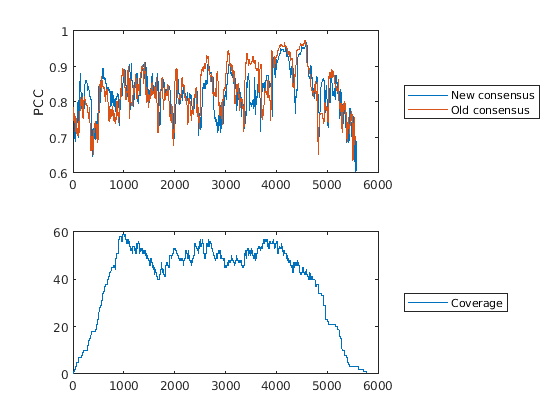

import Core.compare_rescaled_theory;
% compare_rescaled_theory(theoryStruct,sF, wmin,numWorkers)
[mp1, mpI, indexesT, indexesT2] = compare_rescaled_theory(bar, theoryStruct,sF, wmin,numWorkers);

figure,
tiledlayout(2,1)
nexttile
plot(mp1(indexesT{1}(1):indexesT{1}(2)));hold on;
plot(mp1(indexesT{2}(1):indexesT{2}(2)));
ylabel('PCC')
legend({'New consensus','Old consensus'},'Location','eastoutside')
nexttile
plot(sum(~isnan(aaBarcodeIslandBlockRepV)));
legend({'Coverage'},'Location','eastoutside')

mean(mp1(indexesT{1}(1):indexesT{1}(2)),'omitnan')

ans = 0.8283

Re-alignment step

% 
% % % scaled table to map:
% % import Core.consensus_from_table; % todo: better scaling
% % [outConsensus2] = consensus_from_table(valRes{ix}.bbSAll,valRes{ix}.bars);
% 
% wmin = 600;
% 
% import Core.compare_rescaled_theory;
% % compare_rescaled_theory(theoryStruct,sF, wmin,numWorkers)
% [mp1, mpI, indexesT, indexesT2, telapsed] = compare_rescaled_theory(bar, theoryStruct,sF, wmin,numWorkers);
% 
% c = parcluster;
% j1 = batch(c,@compare_rescaled_theory,5,{bar, theoryStruct,sF, wmin,numWorkers});
% % j2 = batch(c,@compare_rescaled_theory,5,{bar, theoryStruct,sF, wmin,10},'Pool',numWorkers-1);
% 
% N = 10;
% wAll = 50:50:N*50;
% j =cell(1,N)
% for i=1:N
%     wmin = wAll(i)
%     j{i} = batch(c,@compare_rescaled_theory,5,{bar, theoryStruct,sF, wmin,numWorkers});
% end
% wait
% % Percentage of barcodes which are better with which method. This allows us
% % to get best w
% percBetter = zeros(1,N);
% for i=1:N
%     r = fetchOutputs(j{i});
%     vals1 = r{1}(r{3}{1}(1):r{3}{1}(2));
%     vals2 = r{1}(r{3}{2}(1):r{3}{2}(2));
%     vals2 = vals2(~isnan(vals1));
%     vals1 = vals1(~isnan(vals1));
%     percBetter(i) = sum(vals1>vals2)/numel(vals1);
% end
% figure,plot(wAll,percBetter)
% 
% figure,plot(vals1);hold on;plot(vals2)
% 
% % 
% % meanVals1 = cellfun(@(x) mean(x.fetchOutputs{1}(x.fetchOutputs{3}{1}(1):x.fetchOutputs{3}{1}(2)),'omitnan'),j);
% % meanVals2 = cellfun(@(x) mean(x.fetchOutputs{1}(x.fetchOutputs{3}{2}(1):x.fetchOutputs{3}{2}(2)),'omitnan'),j);
% 
% % % convert mp-value to p-value
% % alphaN = 0.001; %should be rather insensitive to specific value, check figure S5-S6;
% % nuF = 0.08;
% % l2 = numel(bar{1}.rawBarcode);
% % l1 = numel(theoryStruct.rawBarcode)*sF(end);
% % % p-value for local
% % import Zeromodel.beta_ev_cdf; % correct form?
% % %     pvalfun = @(x,l1,l2,nuF,w) 1-beta_ev_cdf(x,nuF*w,1,nuF*2*(max(l1,l2)-w+1),0);
% % pvalfun = @(x,w) 1-beta_ev_cdf(x,nuF*w,1,max(0.2*2*(max(l1,l2)-w),alphaN*2*(l1-w+1)*(l2-w+1)),0);
% % 
% % figure
% % plot(wAll, arrayfun(@(x,y) pvalfun(x,y),meanVals1,wAll))

Iterative

% iterative_readjustment_consensus
NN = 200;
% wminC
[matRep,consensusNew,barCon,stats,cGen] = iterative_readjustment_consensus(aaBarcodeIslandBlockRepV,barcodeGen, barIslands, cGenAll,ix,wminC,NN,alphaNu1)

jj = 1

Starting comparing exp to theory...
Elapsed time is 4.556052 seconds.
Experiments were compared to theory in 4.5568 seconds


ans = logical
   0


jj = 2

Starting comparing exp to theory...
Elapsed time is 4.598558 seconds.
Experiments were compared to theory in 4.5995 seconds


jj = 3

Starting comparing exp to theory...
Elapsed time is 4.631600 seconds.
Experiments were compared to theory in 4.6324 seconds


ans = logical
   0


jj = 4

Starting comparing exp to theory...
Elapsed time is 4.641731 seconds.
Experiments were compared to theory in 4.6429 seconds


ans = logical
   0


jj = 5

Starting comparing exp to theory...
Elapsed time is 4.633121 seconds.
Experiments were compared to theory in 4.634 seconds


ans = logical
   0


jj = 6

Starting comparing exp to theory...
Elapsed time is 4.626787 seconds.
Experiments were compared to theory in 4.6276 seconds


ans = logical
   0


jj = 7

Starting comparing exp to theory...
Elapsed time is 4.603278 seconds.
Experiments were compared to theory in 4.6041 seconds


ans = logical
   0


jj = 8

Starting comparing exp to theory...
Elapsed time is 4.575830 seconds.
Experiments were compared to theory in 4.5766 seconds


ans = logical
   0


jj = 9

Starting comparing exp to theory...
Elapsed time is 4.578529 seconds.
Experiments were compared to theory in 4.5797 seconds


ans = logical
   0


jj = 10

Starting comparing exp to theory...
Elapsed time is 6.152867 seconds.
Experiments were compared to theory in 6.1537 seconds


ans = logical
   0


jj = 11

Starting comparing exp to theory...
Elapsed time is 4.564786 seconds.
Experiments were compared to theory in 4.5657 seconds


ans = logical
   0


jj = 12

Starting comparing exp to theory...
Elapsed time is 4.581297 seconds.
Experiments were compared to theory in 4.582 seconds


ans = logical
   0


jj = 13

Starting comparing exp to theory...
Elapsed time is 4.583117 seconds.
Experiments were compared to theory in 4.5839 seconds


ans = logical
   0


jj = 14

Starting comparing exp to theory...
Elapsed time is 4.616870 seconds.
Experiments were compared to theory in 4.6176 seconds


ans = logical
   0


jj = 15

Starting comparing exp to theory...
Elapsed time is 4.640230 seconds.
Experiments were compared to theory in 4.6411 seconds


ans = logical
   0


jj = 16

Starting comparing exp to theory...
Elapsed time is 4.579719 seconds.
Experiments were compared to theory in 4.5806 seconds


ans = logical
   0


jj = 17

Starting comparing exp to theory...
Elapsed time is 4.623004 seconds.
Experiments were compared to theory in 4.6238 seconds


ans = logical
   0


jj = 18

Starting comparing exp to theory...
Elapsed time is 4.598649 seconds.
Experiments were compared to theory in 4.5997 seconds


ans = logical
   0


jj = 19

Starting comparing exp to theory...
Elapsed time is 4.591348 seconds.
Experiments were compared to theory in 4.5921 seconds


ans = logical
   0


jj = 20

Starting comparing exp to theory...
Elapsed time is 5.122878 seconds.
Experiments were compared to theory in 5.1236 seconds


ans = logical
   0


jj = 21

Starting comparing exp to theory...
Elapsed time is 4.614724 seconds.
Experiments were compared to theory in 4.6155 seconds


ans = logical
   0


jj = 22

Starting comparing exp to theory...
Elapsed time is 4.587854 seconds.
Experiments were compared to theory in 4.5887 seconds


ans = logical
   0


jj = 23

Starting comparing exp to theory...
Elapsed time is 4.591870 seconds.
Experiments were compared to theory in 4.5926 seconds


ans = logical
   0


jj = 24

Starting comparing exp to theory...
Elapsed time is 4.595438 seconds.
Experiments were compared to theory in 4.5962 seconds


ans = logical
   0


jj = 25

Starting comparing exp to theory...
Elapsed time is 4.616684 seconds.
Experiments were compared to theory in 4.6175 seconds


ans = logical
   0


jj = 26

Starting comparing exp to theory...
Elapsed time is 4.558718 seconds.
Experiments were compared to theory in 4.5597 seconds


ans = logical
   0


jj = 27

Starting comparing exp to theory...
Elapsed time is 4.541537 seconds.
Experiments were compared to theory in 4.5429 seconds


ans = logical
   0


jj = 28

Starting comparing exp to theory...
Elapsed time is 4.525027 seconds.
Experiments were compared to theory in 4.5258 seconds


jj = 29

ans = logical
   0


jj = 30

Starting comparing exp to theory...
Elapsed time is 4.738165 seconds.
Experiments were compared to theory in 4.7389 seconds


ans = logical
   0


jj = 31

Starting comparing exp to theory...
Elapsed time is 4.552123 seconds.
Experiments were compared to theory in 4.553 seconds


ans = logical
   0


jj = 32

Starting comparing exp to theory...
Elapsed time is 4.534018 seconds.
Experiments were compared to theory in 4.5348 seconds


ans = logical
   0


jj = 33

Starting comparing exp to theory...
Elapsed time is 4.517463 seconds.
Experiments were compared to theory in 4.5182 seconds


ans = logical
   0


jj = 34

Starting comparing exp to theory...
Elapsed time is 4.533466 seconds.
Experiments were compared to theory in 4.5343 seconds


ans = logical
   0


jj = 35

Starting comparing exp to theory...
Elapsed time is 4.588099 seconds.
Experiments were compared to theory in 4.5889 seconds


ans = logical
   0


jj = 36

Starting comparing exp to theory...
Elapsed time is 4.553039 seconds.
Experiments were compared to theory in 4.5538 seconds


ans = logical
   0


jj = 37

Starting comparing exp to theory...
Elapsed time is 4.508840 seconds.
Experiments were compared to theory in 4.5097 seconds


ans = logical
   0


jj = 38

Starting comparing exp to theory...
Elapsed time is 4.513005 seconds.
Experiments were compared to theory in 4.5139 seconds


ans = logical
   0


jj = 39

Starting comparing exp to theory...
Elapsed time is 4.539674 seconds.
Experiments were compared to theory in 4.5405 seconds


ans = logical
   0


jj = 40

Starting comparing exp to theory...
Elapsed time is 4.548017 seconds.
Experiments were compared to theory in 4.5488 seconds


ans = logical
   0


jj = 41

Starting comparing exp to theory...
Elapsed time is 4.703232 seconds.
Experiments were compared to theory in 4.704 seconds


ans = logical
   0


jj = 42

Starting comparing exp to theory...
Elapsed time is 4.495972 seconds.
Experiments were compared to theory in 4.4967 seconds


ans = logical
   0


jj = 43

Starting comparing exp to theory...
Elapsed time is 4.474898 seconds.
Experiments were compared to theory in 4.4757 seconds


ans = logical
   0


jj = 44

Starting comparing exp to theory...
Elapsed time is 4.477198 seconds.
Experiments were compared to theory in 4.478 seconds


ans = logical
   0


jj = 45

Starting comparing exp to theory...
Elapsed time is 4.465682 seconds.
Experiments were compared to theory in 4.4666 seconds


ans = logical
   0


jj = 46

Starting comparing exp to theory...
Elapsed time is 4.422510 seconds.
Experiments were compared to theory in 4.4233 seconds


ans = logical
   0


jj = 47

Starting comparing exp to theory...
Elapsed time is 4.476556 seconds.
Experiments were compared to theory in 4.4773 seconds


ans = logical
   0


jj = 48

Starting comparing exp to theory...
Elapsed time is 4.494128 seconds.
Experiments were compared to theory in 4.4955 seconds


ans = logical
   0


jj = 49

Starting comparing exp to theory...
Elapsed time is 4.493185 seconds.
Experiments were compared to theory in 4.4941 seconds


ans = logical
   0


jj = 50

Starting comparing exp to theory...
Elapsed time is 4.524673 seconds.
Experiments were compared to theory in 4.5255 seconds


ans = logical
   0


jj = 51

Starting comparing exp to theory...
Elapsed time is 5.318863 seconds.
Experiments were compared to theory in 5.3197 seconds


ans = logical
   0


jj = 52

Starting comparing exp to theory...
Elapsed time is 4.467012 seconds.
Experiments were compared to theory in 4.4679 seconds


ans = logical
   0


jj = 53

Starting comparing exp to theory...
Elapsed time is 4.485844 seconds.
Experiments were compared to theory in 4.4867 seconds


ans = logical
   0


jj = 54

Starting comparing exp to theory...
Elapsed time is 4.473901 seconds.
Experiments were compared to theory in 4.4746 seconds


ans = logical
   0


jj = 55

Starting comparing exp to theory...
Elapsed time is 4.449270 seconds.
Experiments were compared to theory in 4.4502 seconds


ans = logical
   0


jj = 56

Starting comparing exp to theory...
Elapsed time is 4.476076 seconds.
Experiments were compared to theory in 4.477 seconds


ans = logical
   0


jj = 57

Starting comparing exp to theory...
Elapsed time is 4.481199 seconds.
Experiments were compared to theory in 4.482 seconds


ans = logical
   0


jj = 58

Starting comparing exp to theory...
Elapsed time is 4.445517 seconds.
Experiments were compared to theory in 4.4463 seconds


ans = logical
   0


jj = 59

Starting comparing exp to theory...
Elapsed time is 4.448097 seconds.
Experiments were compared to theory in 4.4489 seconds


ans = logical
   0


jj = 60

Starting comparing exp to theory...
Elapsed time is 4.507504 seconds.
Experiments were compared to theory in 4.5082 seconds


ans = logical
   0


jj = 61

Starting comparing exp to theory...
Elapsed time is 4.416615 seconds.
Experiments were compared to theory in 4.4175 seconds


ans = logical
   0


jj = 62

Starting comparing exp to theory...
Elapsed time is 5.122274 seconds.
Experiments were compared to theory in 5.1232 seconds


ans = logical
   0


jj = 63

Starting comparing exp to theory...
Elapsed time is 4.432564 seconds.
Experiments were compared to theory in 4.4333 seconds


ans = logical
   0


jj = 64

Starting comparing exp to theory...
Elapsed time is 4.440853 seconds.
Experiments were compared to theory in 4.4417 seconds


ans = logical
   0


jj = 65

Starting comparing exp to theory...
Elapsed time is 4.478564 seconds.
Experiments were compared to theory in 4.4795 seconds


ans = logical
   0


jj = 66

Starting comparing exp to theory...
Elapsed time is 4.494253 seconds.
Experiments were compared to theory in 4.4951 seconds


ans = logical
   0


jj = 67

Starting comparing exp to theory...
Elapsed time is 4.437420 seconds.
Experiments were compared to theory in 4.4386 seconds


ans = logical
   0


jj = 68

Starting comparing exp to theory...
Elapsed time is 4.411748 seconds.
Experiments were compared to theory in 4.4126 seconds


ans = logical
   0


jj = 69

Starting comparing exp to theory...
Elapsed time is 4.440954 seconds.
Experiments were compared to theory in 4.4417 seconds


ans = logical
   0


jj = 70

Starting comparing exp to theory...
Elapsed time is 4.402296 seconds.
Experiments were compared to theory in 4.403 seconds


ans = logical
   0


jj = 71

Starting comparing exp to theory...
Elapsed time is 4.418659 seconds.
Experiments were compared to theory in 4.4195 seconds


ans = logical
   0


jj = 72

Starting comparing exp to theory...
Elapsed time is 4.667944 seconds.
Experiments were compared to theory in 4.6688 seconds


ans = logical
   0


jj = 73

Starting comparing exp to theory...
Elapsed time is 4.380446 seconds.
Experiments were compared to theory in 4.3812 seconds


ans = logical
   0


jj = 74

Starting comparing exp to theory...
Elapsed time is 4.449425 seconds.
Experiments were compared to theory in 4.4504 seconds


ans = logical
   0


jj = 75

Starting comparing exp to theory...
Elapsed time is 4.408330 seconds.
Experiments were compared to theory in 4.4092 seconds


ans = logical
   0


jj = 76

Starting comparing exp to theory...
Elapsed time is 4.408050 seconds.
Experiments were compared to theory in 4.4088 seconds


ans = logical
   0


jj = 77

Starting comparing exp to theory...
Elapsed time is 4.402395 seconds.
Experiments were compared to theory in 4.4032 seconds


ans = logical
   0


jj = 78

Starting comparing exp to theory...
Elapsed time is 4.437630 seconds.
Experiments were compared to theory in 4.4384 seconds


ans = logical
   0


jj = 79

Starting comparing exp to theory...
Elapsed time is 4.406300 seconds.
Experiments were compared to theory in 4.4071 seconds


ans = logical
   0


jj = 80

Starting comparing exp to theory...
Elapsed time is 4.418772 seconds.
Experiments were compared to theory in 4.4197 seconds


ans = logical
   0


jj = 81

Starting comparing exp to theory...
Elapsed time is 4.432430 seconds.
Experiments were compared to theory in 4.4332 seconds


ans = logical
   0


jj = 82

Starting comparing exp to theory...
Elapsed time is 4.395776 seconds.
Experiments were compared to theory in 4.3965 seconds


ans = logical
   0


jj = 83

Starting comparing exp to theory...
Elapsed time is 5.692958 seconds.
Experiments were compared to theory in 5.6939 seconds


ans = logical
   0


jj = 84

Starting comparing exp to theory...
Elapsed time is 4.393393 seconds.
Experiments were compared to theory in 4.3942 seconds


ans = logical
   0


jj = 85

Starting comparing exp to theory...
Elapsed time is 4.398700 seconds.
Experiments were compared to theory in 4.3995 seconds


ans = logical
   0


jj = 86

Starting comparing exp to theory...
Elapsed time is 4.421683 seconds.
Experiments were compared to theory in 4.4225 seconds


ans = logical
   0


jj = 87

Starting comparing exp to theory...
Elapsed time is 4.412949 seconds.
Experiments were compared to theory in 4.4138 seconds


ans = logical
   0


jj = 88

Starting comparing exp to theory...
Elapsed time is 4.381236 seconds.
Experiments were compared to theory in 4.3821 seconds


ans = logical
   0


jj = 89

Starting comparing exp to theory...
Elapsed time is 4.434085 seconds.
Experiments were compared to theory in 4.4348 seconds


ans = logical
   0


jj = 90

Starting comparing exp to theory...
Elapsed time is 4.374773 seconds.
Experiments were compared to theory in 4.3755 seconds


ans = logical
   0


jj = 91

Starting comparing exp to theory...
Elapsed time is 4.429893 seconds.
Experiments were compared to theory in 4.4311 seconds


ans = logical
   0


jj = 92

Starting comparing exp to theory...
Elapsed time is 4.335149 seconds.
Experiments were compared to theory in 4.336 seconds


ans = logical
   0


jj = 93

Starting comparing exp to theory...
Elapsed time is 4.382095 seconds.
Experiments were compared to theory in 4.383 seconds


ans = logical
   0


jj = 94

Starting comparing exp to theory...
Elapsed time is 4.357196 seconds.
Experiments were compared to theory in 4.358 seconds


ans = logical
   0


jj = 95

Starting comparing exp to theory...
Elapsed time is 4.383144 seconds.
Experiments were compared to theory in 4.3839 seconds


ans = logical
   0


jj = 96

Starting comparing exp to theory...
Elapsed time is 4.361644 seconds.
Experiments were compared to theory in 4.3624 seconds


ans = logical
   0


jj = 97

Starting comparing exp to theory...
Elapsed time is 4.381368 seconds.
Experiments were compared to theory in 4.3823 seconds


ans = logical
   0


jj = 98

Starting comparing exp to theory...
Elapsed time is 4.349641 seconds.
Experiments were compared to theory in 4.3504 seconds


ans = logical
   0


jj = 99

Starting comparing exp to theory...
Elapsed time is 4.342529 seconds.
Experiments were compared to theory in 4.3434 seconds


ans = logical
   0


jj = 100

Starting comparing exp to theory...
Elapsed time is 4.348487 seconds.
Experiments were compared to theory in 4.3493 seconds


ans = logical
   0


jj = 101

Starting comparing exp to theory...
Elapsed time is 4.370265 seconds.
Experiments were compared to theory in 4.371 seconds


ans = logical
   0


jj = 102

Starting comparing exp to theory...
Elapsed time is 4.338324 seconds.
Experiments were compared to theory in 4.3391 seconds


ans = logical
   0


jj = 103

Starting comparing exp to theory...
Elapsed time is 4.393395 seconds.
Experiments were compared to theory in 4.3943 seconds


ans = logical
   0


jj = 104

Starting comparing exp to theory...
Elapsed time is 4.786010 seconds.
Experiments were compared to theory in 4.7869 seconds


ans = logical
   0


jj = 105

Starting comparing exp to theory...
Elapsed time is 4.337147 seconds.
Experiments were compared to theory in 4.3379 seconds


ans = logical
   0


jj = 106

Starting comparing exp to theory...
Elapsed time is 4.388046 seconds.
Experiments were compared to theory in 4.3889 seconds


ans = logical
   0


jj = 107

Starting comparing exp to theory...
Elapsed time is 4.325257 seconds.
Experiments were compared to theory in 4.3263 seconds


ans = logical
   0


jj = 108

Starting comparing exp to theory...
Elapsed time is 4.367990 seconds.
Experiments were compared to theory in 4.369 seconds


ans = logical
   0


jj = 109

Starting comparing exp to theory...
Elapsed time is 4.366506 seconds.
Experiments were compared to theory in 4.3676 seconds


ans = logical
   0


jj = 110

Starting comparing exp to theory...
Elapsed time is 4.358261 seconds.
Experiments were compared to theory in 4.3591 seconds


ans = logical
   0


jj = 111

Starting comparing exp to theory...
Elapsed time is 4.374097 seconds.
Experiments were compared to theory in 4.375 seconds


ans = logical
   0


jj = 112

Starting comparing exp to theory...
Elapsed time is 4.355835 seconds.
Experiments were compared to theory in 4.3567 seconds


ans = logical
   0


jj = 113

Starting comparing exp to theory...
Elapsed time is 4.499487 seconds.
Experiments were compared to theory in 4.5006 seconds


ans = logical
   0


jj = 114

Starting comparing exp to theory...
Elapsed time is 4.373873 seconds.
Experiments were compared to theory in 4.3747 seconds


ans = logical
   0


jj = 115

Starting comparing exp to theory...
Elapsed time is 5.913899 seconds.
Experiments were compared to theory in 5.915 seconds


ans = logical
   0


jj = 116

Starting comparing exp to theory...
Elapsed time is 4.380652 seconds.
Experiments were compared to theory in 4.3814 seconds


ans = logical
   0


jj = 117

Starting comparing exp to theory...
Elapsed time is 4.322544 seconds.
Experiments were compared to theory in 4.3234 seconds


ans = logical
   0


jj = 118

Starting comparing exp to theory...
Elapsed time is 4.316832 seconds.
Experiments were compared to theory in 4.3176 seconds


ans = logical
   0


jj = 119

Starting comparing exp to theory...
Elapsed time is 4.322878 seconds.
Experiments were compared to theory in 4.3237 seconds


ans = logical
   0


jj = 120

Starting comparing exp to theory...
Elapsed time is 4.329802 seconds.
Experiments were compared to theory in 4.3306 seconds


ans = logical
   0


jj = 121

Starting comparing exp to theory...
Elapsed time is 4.345880 seconds.
Experiments were compared to theory in 4.3467 seconds


ans = logical
   0


jj = 122

Starting comparing exp to theory...
Elapsed time is 4.324827 seconds.
Experiments were compared to theory in 4.3258 seconds


ans = logical
   0


jj = 123

Starting comparing exp to theory...
Elapsed time is 4.292912 seconds.
Experiments were compared to theory in 4.2937 seconds


ans = logical
   0


jj = 124

Starting comparing exp to theory...
Elapsed time is 4.316654 seconds.
Experiments were compared to theory in 4.3176 seconds


ans = logical
   0


jj = 125

Starting comparing exp to theory...
Elapsed time is 4.335391 seconds.
Experiments were compared to theory in 4.3363 seconds


ans = logical
   0


jj = 126

Starting comparing exp to theory...
Elapsed time is 4.372567 seconds.
Experiments were compared to theory in 4.3733 seconds


ans = logical
   0


jj = 127

Starting comparing exp to theory...
Elapsed time is 4.283885 seconds.
Experiments were compared to theory in 4.2846 seconds


ans = logical
   0


jj = 128

Starting comparing exp to theory...
Elapsed time is 4.313974 seconds.
Experiments were compared to theory in 4.3149 seconds


ans = logical
   0


jj = 129

Starting comparing exp to theory...
Elapsed time is 4.306018 seconds.
Experiments were compared to theory in 4.3069 seconds


ans = logical
   0


jj = 130

Starting comparing exp to theory...
Elapsed time is 4.348396 seconds.
Experiments were compared to theory in 4.3492 seconds


ans = logical
   0


jj = 131

Starting comparing exp to theory...
Elapsed time is 4.319205 seconds.
Experiments were compared to theory in 4.32 seconds


ans = logical
   0


jj = 132

Starting comparing exp to theory...
Elapsed time is 4.327698 seconds.
Experiments were compared to theory in 4.3286 seconds


ans = logical
   0


jj = 133

Starting comparing exp to theory...
Elapsed time is 4.292135 seconds.
Experiments were compared to theory in 4.293 seconds


ans = logical
   0


jj = 134

Starting comparing exp to theory...
Elapsed time is 4.315973 seconds.
Experiments were compared to theory in 4.3168 seconds


ans = logical
   0


jj = 135

Starting comparing exp to theory...
Elapsed time is 4.302295 seconds.
Experiments were compared to theory in 4.3031 seconds


ans = logical
   0


jj = 136

Starting comparing exp to theory...
Elapsed time is 5.336357 seconds.
Experiments were compared to theory in 5.3372 seconds


ans = logical
   0


jj = 137

Starting comparing exp to theory...
Elapsed time is 4.280914 seconds.
Experiments were compared to theory in 4.2817 seconds


ans = logical
   0


jj = 138

Starting comparing exp to theory...
Elapsed time is 4.309774 seconds.
Experiments were compared to theory in 4.3106 seconds


ans = logical
   0


jj = 139

Starting comparing exp to theory...
Elapsed time is 4.494323 seconds.
Experiments were compared to theory in 4.4952 seconds


ans = logical
   0


jj = 140

Starting comparing exp to theory...
Elapsed time is 4.331431 seconds.
Experiments were compared to theory in 4.3322 seconds


ans = logical
   0


jj = 141

Starting comparing exp to theory...
Elapsed time is 4.255978 seconds.
Experiments were compared to theory in 4.2567 seconds


ans = logical
   0


jj = 142

Starting comparing exp to theory...
Elapsed time is 4.330631 seconds.
Experiments were compared to theory in 4.3314 seconds


ans = logical
   0


jj = 143

Starting comparing exp to theory...
Elapsed time is 4.273666 seconds.
Experiments were compared to theory in 4.2745 seconds


ans = logical
   0


jj = 144

Starting comparing exp to theory...
Elapsed time is 4.318884 seconds.
Experiments were compared to theory in 4.3197 seconds


ans = logical
   0


jj = 145

Starting comparing exp to theory...
Elapsed time is 4.248918 seconds.
Experiments were compared to theory in 4.2497 seconds


ans = logical
   0


jj = 146

Starting comparing exp to theory...
Elapsed time is 4.254875 seconds.
Experiments were compared to theory in 4.2556 seconds


ans = logical
   0


jj = 147

Starting comparing exp to theory...
Elapsed time is 5.675021 seconds.
Experiments were compared to theory in 5.676 seconds


ans = logical
   0


jj = 148

Starting comparing exp to theory...
Elapsed time is 4.242862 seconds.
Experiments were compared to theory in 4.2437 seconds


ans = logical
   0


jj = 149

Starting comparing exp to theory...
Elapsed time is 4.273150 seconds.
Experiments were compared to theory in 4.2739 seconds


ans = logical
   0


jj = 150

Starting comparing exp to theory...
Elapsed time is 4.382894 seconds.
Experiments were compared to theory in 4.3837 seconds


ans = logical
   0


jj = 151

Starting comparing exp to theory...
Elapsed time is 4.235899 seconds.
Experiments were compared to theory in 4.2367 seconds


ans = logical
   0


jj = 152

Starting comparing exp to theory...
Elapsed time is 4.209769 seconds.
Experiments were compared to theory in 4.2105 seconds


ans = logical
   0


jj = 153

Starting comparing exp to theory...
Elapsed time is 4.221868 seconds.
Experiments were compared to theory in 4.2226 seconds


ans = logical
   0


jj = 154

Starting comparing exp to theory...
Elapsed time is 4.286868 seconds.
Experiments were compared to theory in 4.2877 seconds


ans = logical
   0


jj = 155

Starting comparing exp to theory...
Elapsed time is 4.214846 seconds.
Experiments were compared to theory in 4.2156 seconds


ans = logical
   0


jj = 156

Starting comparing exp to theory...
Elapsed time is 4.262449 seconds.
Experiments were compared to theory in 4.2633 seconds


ans = logical
   0


jj = 157

Starting comparing exp to theory...
Elapsed time is 4.203125 seconds.
Experiments were compared to theory in 4.2039 seconds


ans = logical
   0


jj = 158

Starting comparing exp to theory...
Elapsed time is 4.555384 seconds.
Experiments were compared to theory in 4.5562 seconds


ans = logical
   0


jj = 159

Starting comparing exp to theory...
Elapsed time is 4.222987 seconds.
Experiments were compared to theory in 4.2238 seconds


ans = logical
   0


jj = 160

Starting comparing exp to theory...
Elapsed time is 4.205284 seconds.
Experiments were compared to theory in 4.2062 seconds


ans = logical
   0


jj = 161

Starting comparing exp to theory...
Elapsed time is 4.229860 seconds.
Experiments were compared to theory in 4.2309 seconds


ans = logical
   0


jj = 162

Starting comparing exp to theory...
Elapsed time is 4.206126 seconds.
Experiments were compared to theory in 4.2069 seconds


ans = logical
   0


jj = 163

Starting comparing exp to theory...
Elapsed time is 4.200360 seconds.
Experiments were compared to theory in 4.2012 seconds


ans = logical
   0


jj = 164

Starting comparing exp to theory...
Elapsed time is 4.227446 seconds.
Experiments were compared to theory in 4.2282 seconds


ans = logical
   0


jj = 165

Starting comparing exp to theory...
Elapsed time is 4.219068 seconds.
Experiments were compared to theory in 4.2203 seconds


ans = logical
   0


jj = 166

Starting comparing exp to theory...
Elapsed time is 4.259385 seconds.
Experiments were compared to theory in 4.2601 seconds


ans = logical
   0


jj = 167

Starting comparing exp to theory...
Elapsed time is 4.260746 seconds.
Experiments were compared to theory in 4.2615 seconds


ans = logical
   0


jj = 168

Starting comparing exp to theory...
Elapsed time is 4.202314 seconds.
Experiments were compared to theory in 4.2031 seconds


ans = logical
   0


jj = 169

Starting comparing exp to theory...
Elapsed time is 4.797780 seconds.
Experiments were compared to theory in 4.7987 seconds


ans = logical
   0


jj = 170

Starting comparing exp to theory...
Elapsed time is 4.254164 seconds.
Experiments were compared to theory in 4.2555 seconds


ans = logical
   0


jj = 171

Starting comparing exp to theory...
Elapsed time is 4.247731 seconds.
Experiments were compared to theory in 4.2485 seconds


ans = logical
   0


jj = 172

Starting comparing exp to theory...
Elapsed time is 4.301892 seconds.
Experiments were compared to theory in 4.303 seconds


ans = logical
   0


jj = 173

Starting comparing exp to theory...
Elapsed time is 4.247503 seconds.
Experiments were compared to theory in 4.2482 seconds


ans = logical
   0


jj = 174

Starting comparing exp to theory...
Elapsed time is 4.163486 seconds.
Experiments were compared to theory in 4.1644 seconds


ans = logical
   0


jj = 175

Starting comparing exp to theory...
Elapsed time is 4.187236 seconds.
Experiments were compared to theory in 4.1881 seconds


ans = logical
   0


jj = 176

Starting comparing exp to theory...
Elapsed time is 4.236841 seconds.
Experiments were compared to theory in 4.2376 seconds


ans = logical
   0


jj = 177

Starting comparing exp to theory...
Elapsed time is 4.235213 seconds.
Experiments were compared to theory in 4.2359 seconds


ans = logical
   0


jj = 178

Starting comparing exp to theory...
Elapsed time is 4.231066 seconds.
Experiments were compared to theory in 4.2318 seconds


ans = logical
   0


jj = 179

Starting comparing exp to theory...
Elapsed time is 4.217395 seconds.
Experiments were compared to theory in 4.2181 seconds


ans = logical
   0


jj = 180

Starting comparing exp to theory...
Elapsed time is 5.609985 seconds.
Experiments were compared to theory in 5.6108 seconds


ans = logical
   0


jj = 181

Starting comparing exp to theory...
Elapsed time is 4.180900 seconds.
Experiments were compared to theory in 4.1816 seconds


ans = logical
   0


jj = 182

Starting comparing exp to theory...
Elapsed time is 4.207868 seconds.
Experiments were compared to theory in 4.2088 seconds


ans = logical
   0


jj = 183

Starting comparing exp to theory...
Elapsed time is 4.362914 seconds.
Experiments were compared to theory in 4.3638 seconds


ans = logical
   0


jj = 184

Starting comparing exp to theory...
Elapsed time is 4.196758 seconds.
Experiments were compared to theory in 4.1976 seconds


ans = logical
   0


jj = 185

Starting comparing exp to theory...
Elapsed time is 4.207087 seconds.
Experiments were compared to theory in 4.2079 seconds


ans = logical
   0


jj = 186

Starting comparing exp to theory...
Elapsed time is 4.172427 seconds.
Experiments were compared to theory in 4.1732 seconds


ans = logical
   0


jj = 187

Starting comparing exp to theory...
Elapsed time is 4.164796 seconds.
Experiments were compared to theory in 4.1657 seconds


ans = logical
   0


jj = 188

Starting comparing exp to theory...
Elapsed time is 4.214463 seconds.
Experiments were compared to theory in 4.2156 seconds


ans = logical
   0


jj = 189

Starting comparing exp to theory...
Elapsed time is 4.195164 seconds.
Experiments were compared to theory in 4.1959 seconds


ans = logical
   0


jj = 190

Starting comparing exp to theory...
Elapsed time is 4.164710 seconds.
Experiments were compared to theory in 4.1655 seconds


ans = logical
   0


jj = 191

Starting comparing exp to theory...
Elapsed time is 5.680762 seconds.
Experiments were compared to theory in 5.6819 seconds


ans = logical
   0


jj = 192

Starting comparing exp to theory...
Elapsed time is 4.258069 seconds.
Experiments were compared to theory in 4.2588 seconds


ans = logical
   0


jj = 193

Starting comparing exp to theory...
Elapsed time is 4.162049 seconds.
Experiments were compared to theory in 4.1628 seconds


ans = logical
   0


jj = 194

Starting comparing exp to theory...
Elapsed time is 4.242273 seconds.
Experiments were compared to theory in 4.243 seconds


ans = logical
   0


jj = 195

Starting comparing exp to theory...
Elapsed time is 4.118277 seconds.
Experiments were compared to theory in 4.119 seconds


ans = logical
   0


jj = 196

Starting comparing exp to theory...
Elapsed time is 4.173699 seconds.
Experiments were compared to theory in 4.1744 seconds


ans = logical
   0


jj = 197

Starting comparing exp to theory...
Elapsed time is 4.175573 seconds.
Experiments were compared to theory in 4.1764 seconds


ans = logical
   0


jj = 198

Starting comparing exp to theory...
Elapsed time is 4.258321 seconds.
Experiments were compared to theory in 4.2591 seconds


ans = logical
   0


jj = 199

Starting comparing exp to theory...
Elapsed time is 4.196816 seconds.
Experiments were compared to theory in 4.1975 seconds


ans = logical
   0


jj = 200

Starting comparing exp to theory...
Elapsed time is 4.204394 seconds.
Experiments were compared to theory in 4.2051 seconds


ans = logical
   0


matRep = 1×201 cell array
    {307×5783 double}    {308×5778 double}    {309×5773 double}    {308×5768 double}    {309×5763 double}    {309×5758 double}    {309×5753 double}    {309×5748 double}    {309×5739 double}    {309×5734 double}    {309×5729 double}    {309×5724 double}    {309×5719 double}    {309×5713 double}    {309×5708 double}    {309×5703 double}    {309×5698 double}    {309×5693 double}    {309×5686 double}    {309×5681 double}    {309×5676 double}    {309×5671 double}    {309×5666 double}    {309×5661 double}    {309×5656 double}    {309×5614 double}    {309×5608 double}    {309×5602 double}    {309×5597 double}    {309×5592 double}    {308×5587 double}    {307×5583 double}    {307×5579 double}    {307×5575 double}    {307×5571 double}    {307×5567 double}    {307×5563 double}    {307×5559 double}    {307×5555 double}    {307×5551 double}    {307×5534 double}    {307×5530 double}    {307×5526 double}    {308×5519 double}    {308×5512 double}    {308×5508 double}    {308

consensusNew = 1×201 cell array
    {[NaN NaN NaN NaN NaN 142.1665 142.3484 … ]}    {[NaN NaN NaN NaN NaN 121.7729 121.8685 … ]}    {[NaN NaN NaN NaN NaN 128.4154 128.5019 … ]}    {[NaN NaN NaN NaN NaN 122.4083 122.4202 … ]}    {[NaN NaN NaN NaN NaN 122.6355 122.6285 … ]}    {[NaN NaN NaN NaN NaN 119.4145 119.4076 … ]}    {[NaN NaN NaN NaN NaN 119.5027 119.4766 … ]}    {[NaN NaN NaN NaN 118.3965 119.9538 … ]}    {[NaN NaN NaN NaN NaN 119.3551 115.4960 … ]}    {[NaN NaN NaN NaN NaN 119.9422 118.0666 … ]}    {[NaN NaN NaN NaN NaN 120.1331 117.9999 … ]}    {[NaN NaN NaN NaN NaN 119.8718 117.8833 … ]}    {[NaN NaN NaN NaN NaN 117.2176 117.0181 … ]}    {[NaN NaN NaN NaN NaN 118.5709 113.6513 … ]}    {[NaN NaN NaN NaN NaN 128.0167 124.7998 … ]}    {[NaN NaN NaN NaN NaN 118.8785 125.4448 … ]}    {[NaN NaN NaN NaN NaN 131.4589 127.2691 … ]}    {[NaN NaN NaN NaN NaN 131.3613 127.3334 … ]}    {[NaN NaN NaN NaN NaN 121.6169 118.9953 … ]}    {[NaN NaN NaN NaN NaN 109.3492 105.1480 … ]}    {[NaN Na

barCon = 1×201 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struc

stats = struct with fields:
    score: {1×200 cell}


cGen = 1×200 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}

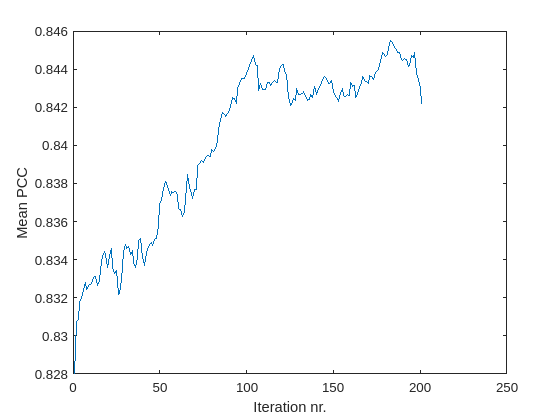



sFRe = 0.85:0.01:1.15;

import Core.compare_rescaled_theory;
% compare_rescaled_theory(theoryStruct,sF, wmin,numWorkers)
[mp1, mpI, indexesT, indexesT2] = compare_rescaled_theory(barCon, theoryStruct, sFRe, wmin, numWorkers);

    vals1best = cellfun(@(x) nanmean(mp1(x(1):x(2))),indexesT,'un',true);
    vals1all = cellfun(@(x) mp1(x(1):x(2)),indexesT,'un',false);

    figure,plot(vals1best)
    xlabel('Iteration nr.')
    ylabel('Mean PCC')

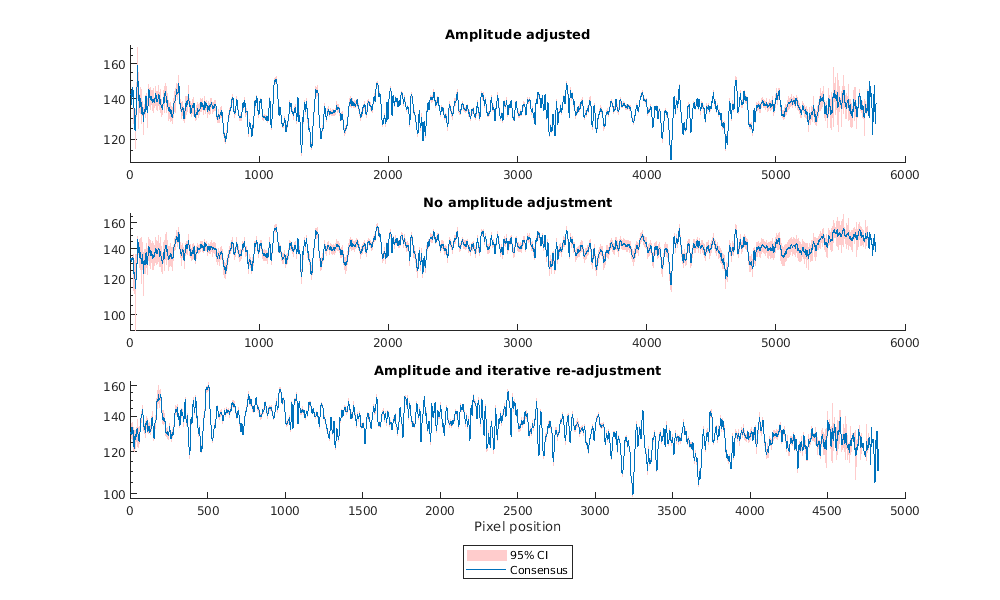

f =   Figure (35) with properties:

      Number: 35
        Name: ''
       Color: [1 1 1]
    Position: [1 1 1000 600]
       Units: 'pixels'

  Show all properties




  f = consensus_ci(aaBarcodeIslandBlockRepV,rawBarcodeIslandBlockRep,matRep{end})

   % print('FIGS/FigS9.eps','-depsc','-r500');


% %% Using PCC:
% 
% %%  consensus vs theory
% % First generate theory:
% w = 300;% minimum overlap length
% % sF = 0.9:0.025:1.1;
% timestamp = datestr(clock(), 'yyyy-mm-dd_HH_MM_SS');
% 
% fastas = {'018_final_polish.fasta','DA32087.fasta','DA68335.fasta'};
% theoryIdxs = {1, 3, 2, nan, 2 , 2, 3}; % known theory indexes
% dataSetIdx = 3; % 5,... test datasets (part of the data)
% 
% nmPerPx = 110;
% nmbp = 0.25; % ? 
% 
% % quickly calculate theory for given single fasta file
% [theoryStructRev,theoryStruct,bT] = prep_thry_for_local_comp(fastas(theoryIdxs{dataSetIdx}), nmbp, nmPerPx, 1);
% 
% %%
% sF = 0.9:0.01:1.1;
% theoryStruct.rawBitmask = zeros(1,length(theoryStruct.rawBarcode));
% import Core.rescale_barcode_data;
% [tsRescaled] = rescale_barcode_data({theoryStruct},sF);
% 
% import SignalRegistration.masked_multidim_pcc_corr;
% maxCoefsConsensus = zeros(1,length(consensusNew));  
% for k=1:length(consensusNew)
%     xcorrsBest = cell(1,length(tsRescaled{1}.rescaled));
%     for i=1:length(tsRescaled{1}.rescaled)
%         [ xcorrsBest{i}, ~ ] = masked_multidim_pcc_corr( consensusNew{k}',tsRescaled{1}.rescaled{i}.rawBarcode',~isnan(consensusNew{k})',~isnan(tsRescaled{1}.rescaled{i}.rawBarcode)',300);
%     end
%     
%     zMethod = 'meanpcc';
%     scoreSingleConsensus = cell(1,length(xcorrsBest));
%     for i=1:length(xcorrsBest)
%         [maxScore,maxPos] = max(xcorrsBest{i},[],1);
%         % first take max over 3rd dim
%         [scoreMaxOr,scoreMaxOrPos] = max(xcorrsBest{i},[],3);
%         switch zMethod
%             %             case 'stouffer'
%             %             case 'fisher'
%             case 'meanpcc'
%                 scoreSingleConsensus{i} = mean(scoreMaxOr,2);
%             otherwise
%                 error('No such method for combining p-values')
%         end
%     end
%     
%     maxCoefsConsensus(k) = max(cellfun(@(x) max(x),scoreSingleConsensus));
% 
% end
% 
% %
% figure,plot(maxCoefsConsensus);
% xlabel('Iteration')
% ylabel('Max PCC consensus vs theory')

Best reference based positions

[barConRef,Z , allscores,clusterBarcodesV] = ref_based_consensus(theoryStruct,cGenAll,ix,barcodeGen,barIslands,wminC,sFRe);

Starting comparing exp to theory...
Elapsed time is 23.416946 seconds.
Experiments were compared to theory in 23.4177 seconds



import Core.compare_rescaled_theory;
% compare_rescaled_theory(theoryStruct,sF, wmin,numWorkers)
[mp1Ref, mpIRef, indexesTRef, indexesT2Ref] = compare_rescaled_theory(barConRef, theoryStruct, sFRe, wmin, numWorkers);

vals1bestRef = cellfun(@(x) nanmean(mp1Ref(x(1):x(2))),indexesTRef,'un',true);
 vals1all = cellfun(@(x) mp1(x(1):x(2)),indexesT,'un',false);
sum(barConRef{1}.rawBitmask)

ans = 5079

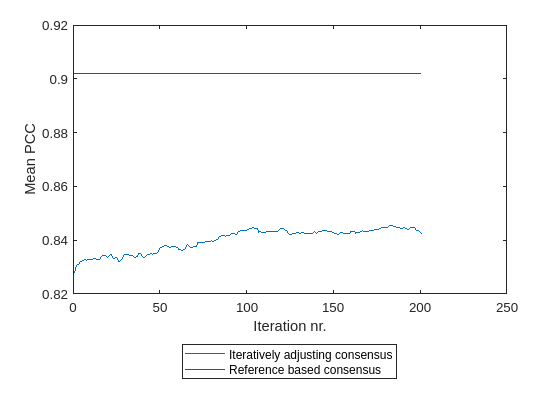


figure,plot(vals1best)
xlabel('Iteration nr.')
ylabel('Mean PCC')
hold on
plot(1:length(vals1best),repmat(vals1bestRef,1,length(vals1best)),'red-');
legend({'Iteratively adjusting consensus','Reference based consensus'},'Location','southoutside')

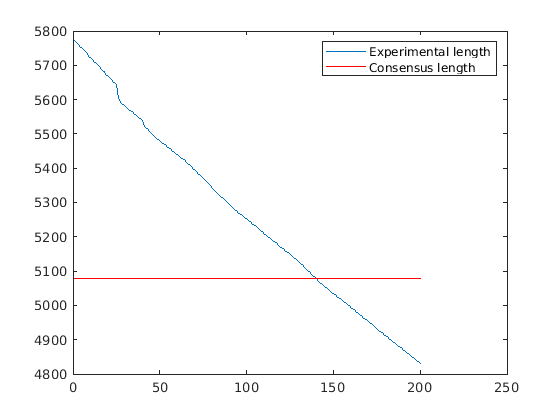



figure,plot(cellfun(@(x) sum(x.rawBitmask),barCon))
hold on
plot(1:length(vals1best),repmat(sum(barConRef{1}.rawBitmask),1,length(vals1best)),'red-');
legend({'Experimental length','Consensus length'})


% %% Using PCC:
% sum(barConRef{1}.rawBitmask)
